read stats for every continent

analysis_AF = tdfread('../analysis_2020_08/lcc_AF.csv', ",");
analysis_AS = tdfread('../analysis_2020_08/lcc_AS.csv', ',');
analysis_EU = tdfread('../analysis_2020_08/lcc_EU.csv', ',');
analysis_NA = tdfread('../analysis_2020_08/lcc_NA.csv', ',');
analysis_OC = tdfread('../analysis_2020_08/lcc_OC.csv', ',');
analysis_SA = tdfread('../analysis_2020_08/lcc_SA.csv', ',');
analysis_MANY = tdfread('../analysis_2020_08/lcc_MANY.csv', ',');

extract LCC cov distributions ordered

lcc_cov_AF = sortrows(analysis_AF.largest_cc_coverage);
lcc_cov_AS = sortrows(analysis_AS.largest_cc_coverage);
lcc_cov_EU = sortrows(analysis_EU.largest_cc_coverage);
lcc_cov_NA = sortrows(analysis_NA.largest_cc_coverage);
lcc_cov_OC = sortrows(analysis_OC.largest_cc_coverage);
lcc_cov_SA = sortrows(analysis_SA.largest_cc_coverage);
lcc_cov_MANY = sortrows(analysis_MANY.largest_cc_coverage);

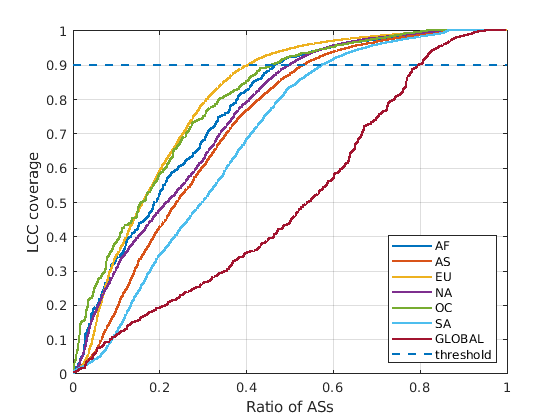

clf
max_len = length(lcc_cov_EU);
new_lcc_AF = norm_plot(max_len, lcc_cov_AF);
plot(new_lcc_AF, 'DisplayName', 'AF', "LineWidth",1.5)
hold on
new_lcc_AS = norm_plot(max_len, lcc_cov_AS);
plot(new_lcc_AS, 'DisplayName', 'AS', "LineWidth",1.5)
new_lcc_EU = norm_plot(max_len, lcc_cov_EU);
plot(lcc_cov_EU, 'DisplayName', 'EU', "LineWidth",1.5)
new_lcc_NA = norm_plot(max_len, lcc_cov_NA);
plot(new_lcc_NA, 'DisplayName', 'NA', "LineWidth",1.5)
new_lcc_OC = norm_plot(max_len, lcc_cov_OC);
plot(new_lcc_OC, 'DisplayName', 'OC', "LineWidth",1.5)
new_lcc_SA = norm_plot(max_len, lcc_cov_SA);
plot(new_lcc_SA, 'DisplayName', 'SA', "LineWidth",1.5)
new_lcc_MANY = norm_plot(max_len, lcc_cov_MANY);
plot(new_lcc_MANY, 'DisplayName', 'GLOBAL', "LineWidth",1.5)
plot(0.9*ones(max_len,1), 'DisplayName', 'threshold', "LineStyle","--", "LineWidth",1.5)
legend("Location","southeast")
xlim([0 max_len])
xticks([0:max_len/5:max_len])
xticklabels({'0', '0.2', '0.4', '0.6', '0.8', '1'})
grid on
xlabel("Ratio of ASs")
ylabel("LCC coverage")
hold off

read stats for every country

analysis_BR = tdfread('../analysis_2020_08/lcc_BR.csv', ",");
analysis_CN = tdfread('../analysis_2020_08/lcc_CN.csv', ',');
analysis_DE = tdfread('../analysis_2020_08/lcc_DE.csv', ',');
analysis_FR = tdfread('../analysis_2020_08/lcc_FR.csv', ',');
analysis_IT = tdfread('../analysis_2020_08/lcc_IT.csv', ',');
analysis_JP = tdfread('../analysis_2020_08/lcc_JP.csv', ',');
analysis_RU = tdfread('../analysis_2020_08/lcc_RU.csv', ',');
analysis_US = tdfread('../analysis_2020_08/lcc_US.csv', ',');

extract LCC cov distributions ordered

lcc_cov_BR = sortrows(analysis_BR.largest_cc_coverage);
lcc_cov_CN = sortrows(analysis_CN.largest_cc_coverage);
lcc_cov_DE = sortrows(analysis_DE.largest_cc_coverage);
lcc_cov_FR = sortrows(analysis_FR.largest_cc_coverage);
lcc_cov_IT = sortrows(analysis_IT.largest_cc_coverage);
lcc_cov_JP = sortrows(analysis_JP.largest_cc_coverage);
lcc_cov_RU = sortrows(analysis_RU.largest_cc_coverage);
lcc_cov_US = sortrows(analysis_US.largest_cc_coverage);

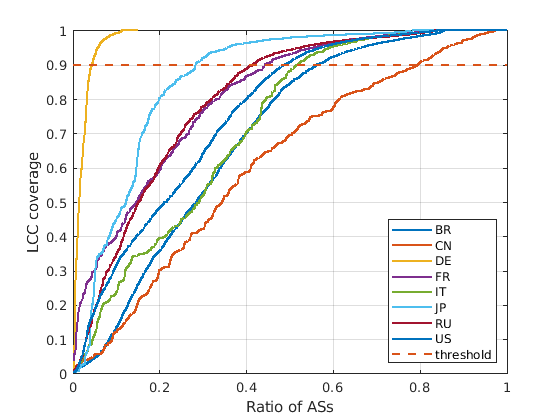

clf
max_len = length(lcc_cov_US);
new_lcc_BR = norm_plot(max_len, lcc_cov_BR);
plot(new_lcc_BR, 'DisplayName', 'BR', "LineWidth",1.5)
hold on
new_lcc_CN = norm_plot(max_len, lcc_cov_CN);
plot(new_lcc_CN, 'DisplayName', 'CN', "LineWidth",1.5)
new_lcc_DE = norm_plot(max_len, lcc_cov_DE);
plot(lcc_cov_DE, 'DisplayName', 'DE', "LineWidth",1.5)
new_lcc_FR = norm_plot(max_len, lcc_cov_FR);
plot(new_lcc_FR, 'DisplayName', 'FR', "LineWidth",1.5)
new_lcc_IT = norm_plot(max_len, lcc_cov_IT);
plot(new_lcc_IT, 'DisplayName', 'IT', "LineWidth",1.5)
new_lcc_JP = norm_plot(max_len, lcc_cov_JP);
plot(new_lcc_JP, 'DisplayName', 'JP', "LineWidth",1.5)
new_lcc_RU = norm_plot(max_len, lcc_cov_RU);
plot(new_lcc_RU, 'DisplayName', 'RU', "LineWidth",1.5)
new_lcc_US = norm_plot(max_len, lcc_cov_US);
plot(new_lcc_US, 'DisplayName', 'US', "LineWidth",1.5)
plot(0.9*ones(max_len,1), 'DisplayName', 'threshold', "LineStyle","--", "LineWidth",1.5)
legend("Location","southeast")
xlim([0 max_len])
xticks([0:max_len/5:max_len])
xticklabels({'0', '0.2', '0.4', '0.6', '0.8', '1'})
grid on
xlabel("Ratio of ASs")
ylabel("LCC coverage")
hold off

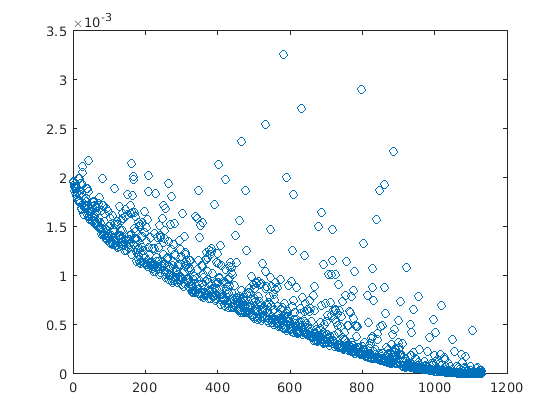

density_matrix = [analysis.ds_links analysis.density_lcc];
density_matrix = rmmissing(sortrows(density_matrix, 1));
plot(density_matrix(:,2), 'o');

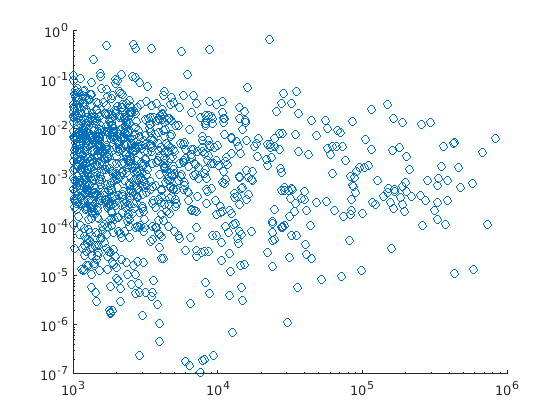

trans_nodes = rmmissing([analysis.ds_nodes analysis.transitivity_lcc]);
scatter(trans_nodes(:,1), trans_nodes(:,2));
set(gca,'xscale','log');
set(gca,'yscale','log');

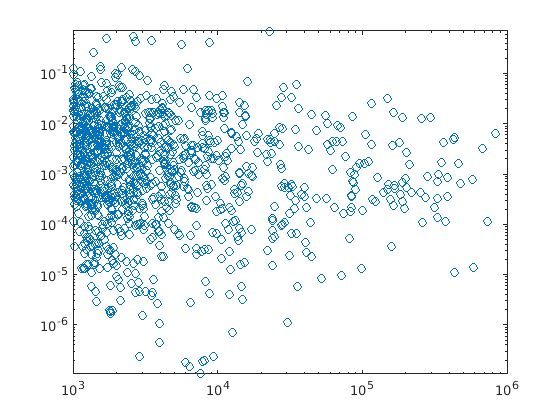

plot(trans_nodes(:,1), trans_nodes(:,2), 'o')
lsline
set(gca,'xscale','log');
set(gca,'yscale','log');

% lsline